# Task4

Load the image

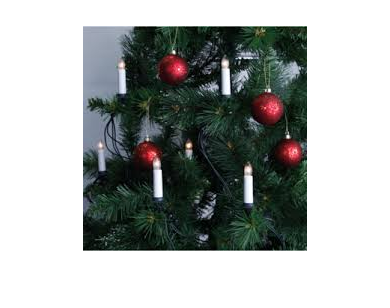

rgb = imread("../redball.jpeg");
figure;imshow(rgb);

Now we have the correct number of balls

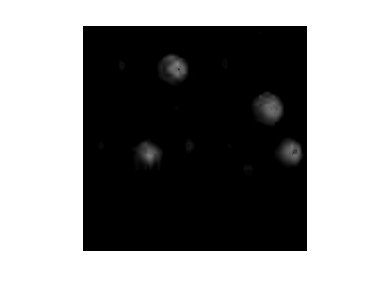

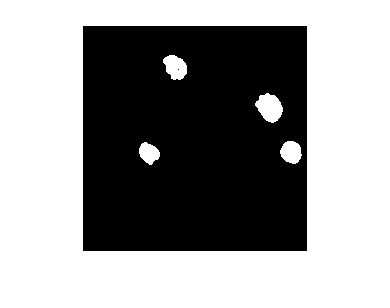

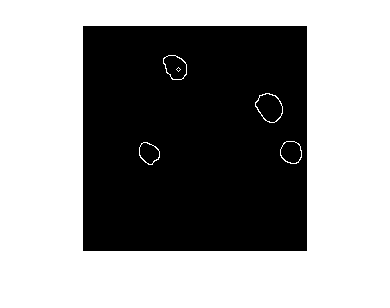

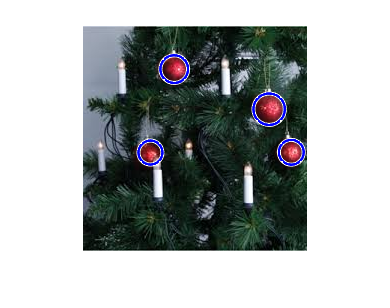

There are 4 balls in the image

fprintf("There are %d balls in the image",count_red_balls(rgb,1));

This sollution works good when the balls are red, however finding green or som other color balls would be much harder in this image.

A function that counts the red balls in an image

function n = count_red_balls(rgb,disp)

Only keep the red layer, since we want to find red things

    img= rgb(:,:,1)-im2gray(rgb); % Remove intensity map
    if disp
        figure;imshow(img);
    end

Segment the image, creating a classification image

    % Segment with k-means, we want two classes since we want, ball or no ball
    [img, ~]= imsegkmeans(img,2);
    img = remap(img);
    if disp
        figure;imshow(img);
    end

Find ball perimiters

    % Extract the ball borders
    img = edge(img,"canny");
    if disp
        figure;imshow(img);
    end

Find circles using hough transform with the parametisation 

(a-x)^2 - (b-y)^2 = r^2

where r is itterated over

Here is the recomended calling convention for imfindcircles.

    [centers, radii, ~] = imfindcircles(img,[10,20]);
    if disp
        figure;imshow(rgb);
        viscircles(centers, radii,'EdgeColor','b');
    end
    n = size(centers,1);
    function o = remap(inp)
        map = [0,1];
        o = inp == 0;
        for i = 1:size(inp,1)
            for j = 1:size(inp,2)
                o(i,j) = map(inp(i,j));
            end
        end
    end
end
